# Demo 3 - Visualization Functions

## Load and pre-process three data sets, X, Y and Z

cdgea; % set working directory
[X,genelistx] = sc_readfile(pkg.i_exampledata('GSM3204304_P_P_Expr.csv'));

Reading example_data/GSM3204304_P_P_Expr.csv ...... done.


[Y,genelisty] = sc_readfile(pkg.i_exampledata('GSM3204305_P_N_Expr.csv'));

Reading example_data/GSM3204305_P_N_Expr.csv ...... done.


[Z,genelistz] = sc_readfile(pkg.i_exampledata('GSM3044891_GeneExp.UMIs.10X1.txt'));

Reading example_data/GSM3044891_GeneExp.UMIs.10X1.txt ...... done.


[X,genelistx] = sc_selectg(X, genelistx, 3, 1);
[Y,genelisty] = sc_selectg(Y, genelisty, 3, 1);
[Z,genelistz] = sc_selectg(Z, genelistz, 3, 1);

## Intersection of common genes in X, Y and Z

[genelist] = intersect(intersect(genelistx, genelisty, 'stable'), genelistz, 'stable');
% Remove genes encoded in the mitochondrial genome
i=startsWith(genelist, 'MT-');
genelist(i) = [];
[~,i1] = ismember(genelist, genelistx);
[~,i2] = ismember(genelist, genelisty);
[~,i3] = ismember(genelist, genelistz);
X=X(i1,:); genelistx = genelist;
Y=Y(i2,:); genelisty = genelist;
Z=Z(i3,:); genelistz = genelist;
% [X]=sc_norm(X,'type','deseq');
% [Y]=sc_norm(Y,'type','deseq');
% [Z]=sc_norm(Z,'type','deseq');

## Label cells

cellidx = [1*ones(size(X,2),1); 2*ones(size(Y,2),1); 3*ones(size(Z, 2), 1)];

## PCA

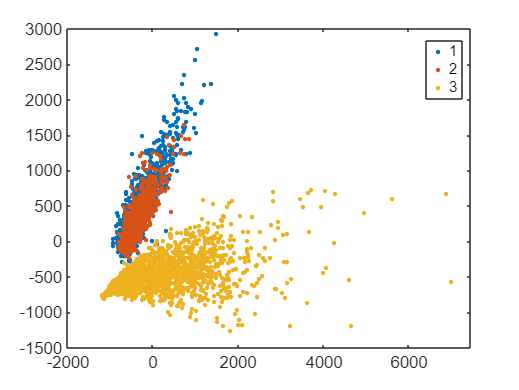

[~,s]=pca([X Y Z]');
gscatter(s(:,1), s(:,2), cellidx, '', '', 8);

## t-SNE

[s]=sc_tsne([X Y Z],2,false,true);

log1p transformation...done.


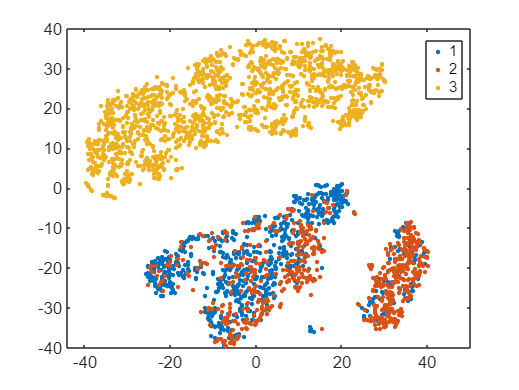

gscatter(s(:,1), s(:,2), cellidx, '', '', 8);

## Diffusion Map

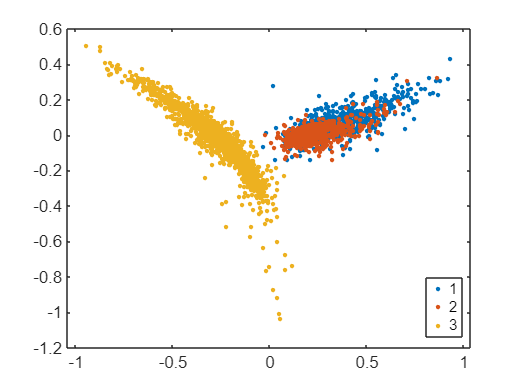

[s] = run.ml_diffuse([X Y Z]);
gscatter(s(:,1), s(:,2), cellidx, '', '', 8);

## Scatter plots

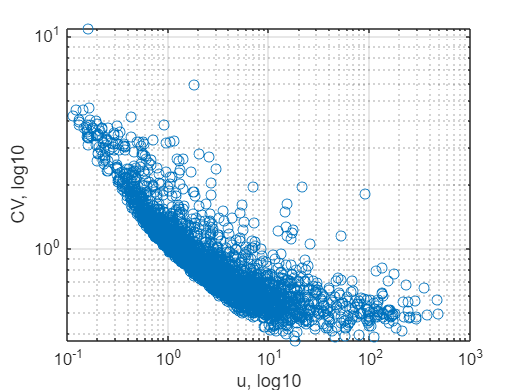

figure;
gui.sc_scattergenes(X, genelistx, 'mean_cv');

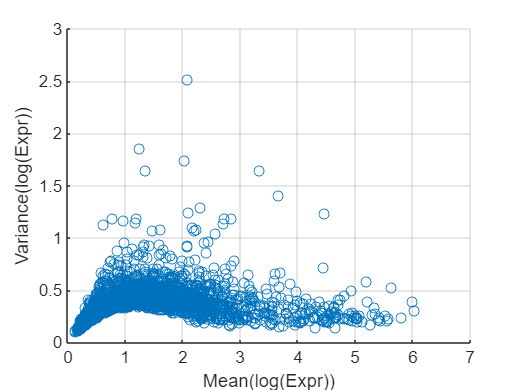


figure;
gui.sc_scattergenes(X, genelistx, 'meanlg_varlg');

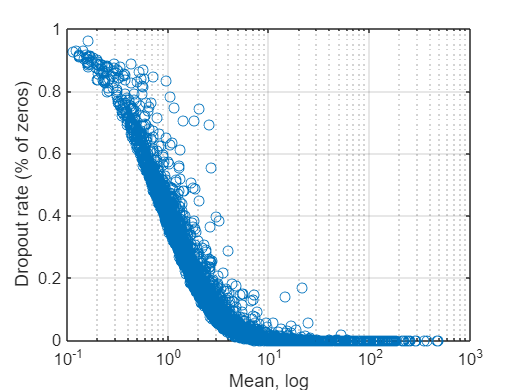


figure;
gui.sc_scattergenes(X, genelistx, 'mean_dropr');

## 3D scatter plot with spline fit

Processing your data...... scGEAToolbox controls for the variance-mean relationship of gene
expression. scGEAToolbox considers three sample statistics of each
gene: expression mean⁠, coefficient of variation⁠, and dropout rate⁠.
After normalization, it fits a spline function based on piece-wise
polynomials to model the relationship among the three statistics, 
and calculates the distance between each geneis observed statistics
to the fitted 3D spline surface. Genes with larger distances are 
ranked higher for feature selection.
Elapsed time is 0.497035 seconds.


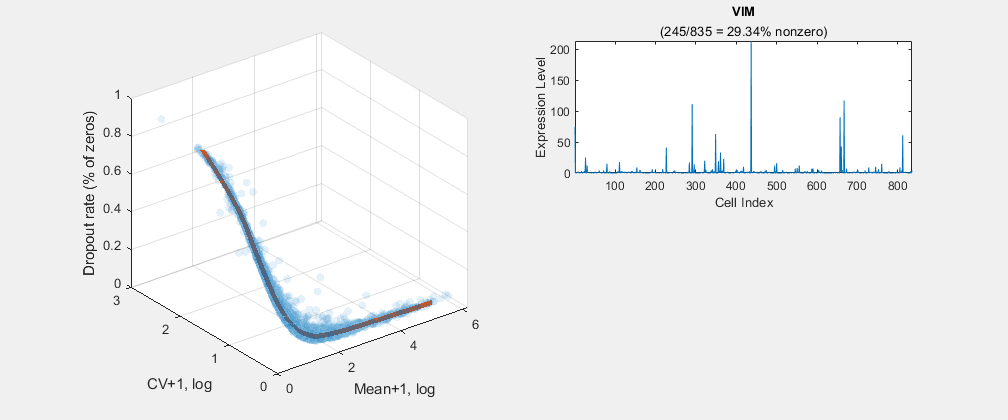

figure;
gui.i_hvgcurveplot(X, genelistx, true, true, [], "splinefit");

## Feature selection and show top 50 differentially deviated (DD) genes

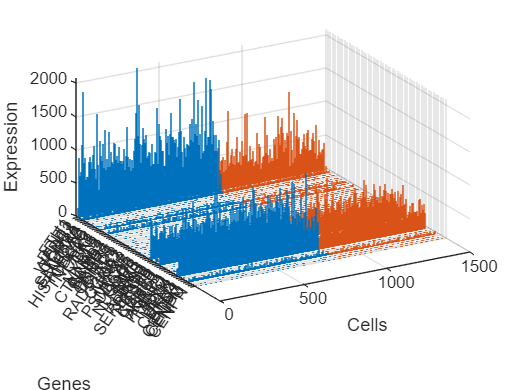

T = sc_splinefit2(X, Y, genelistx, genelisty);
T = sortrows(T, size(T,2), 'descend');
[~,idx1] = ismember(table2array(T(:,1)), genelistx);
[~,idx2] = ismember(table2array(T(:,1)), genelisty);
figure;
gui.sc_stem3(X(idx1,:), Y(idx2,:), genelistx(idx1), 50);

## The End